# Assignment 2: Fourier Analysis

## G**eneral Instructions:**

- Make sure you use the exact function declarations given in the question descriptions. **Changes of any kind will be penalized.**

- Save every function in a separate .m file with the correct function name (e.g. functionName.m)

- Plots and discussion should be included in this Live Script (.mlx) file itself

- Plots should be properly and extensively labeled.

- Core MATLAB functions are allowed. Functions from toolboxes (such as Signal Processing Toolbox) are **not allowed** unless explicitly specified otherwise.

- Submit the MATLAB code as a link to a private github repository share with me and upload the .pdf report to canvas

- Clarification edits will be shown in **bold**.

- **STRONGLY RECOMMENDED: **Clear all variables and run this script in its entirety before submission. Make sure everything runs okay **in one go** from top to bottom.

The purpose of this assignment is to cover some of the concepts associated with Fourier transforms and spectrograms

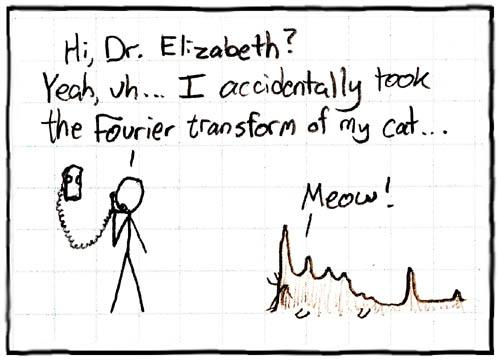

% INITIALIZATION CODE. DO NOT CHANGE.

clearvars;

restoredefaultpath;

% Determine where your mlx-file's folder is.
assignmentFolder = fileparts(fileparts(matlab.desktop.editor.getActiveFilename)); 
% Add that folder plus all subfolders to the path.
addpath(genpath(assignmentFolder));

## Question 0: ** Setting up the MATLAB script [5]**

Create your copy of this MATLAB Live Script (.mlx) titled `assignment2.mlx`.

This script should call the functions below in the specified order, read the files, and generate all the required plots / figures (with proper axes and labels wherever required). This script will be executed for grading.  

Set the variable `studentId` to your GT username (e.g. `gburdell3, alerch3, kwatchar3`). **DO NOT USE YOUR EMAIL ALIAS.**

% CHANGE THIS
studentId = 'kwatchar3'; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
score = 100; % SCORE OUT OF 100
autograde('q0', struct('score', score), studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Question 1: **Generating sinusoids in MATLAB [15]**

### Q1(a) [10]

Write a function 

`[t, x] = generateSinusoidal(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian)` 

generating a sinusoidal according to the parameters. 

**Use an appropriate trigonometric function so that when **`phase_radian`** is zero, **`x(1)`** is zero.**

The outputs `x` and `t` are the generated signal and the corresponding time **in seconds**, respectively. Both outputs must be column vectors of the same length (`N` by `1`).

**Quick check:** `t(n+1) - t(n)` should be equal to `1/frequency_hz` up to machine precision, for all `n`. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1a', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(b) [2.5]

Add a function call to your script to generate a sine wave with the following parameters: 

- amplitude = 1.0, 

- sample_rate_hz = 44100 Hz

- frequency_hz = 400 Hz, 

- length_sec = 0.5 s, 

- phase_radian = $\frac{\pi }{2}$ rad.

% ADD YOUR CODE



% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1b', struct(), studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(c) [2.5]

Plot the first 5 ms of the sinusoid generated in Part 2. above (label the axes correctly, time axis must be in seconds)

% ADD YOUR CODE


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
plotScore = NaN; % SCORE OUT OF 100
autograde('q1c', struct('plotScore', plotScore), studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 2: Combining Sinusoids to generate waveforms with complex spectra [20]**

### Q2(a) [15]

Write a function 

`[t,x] = generateSquare(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian)`

that generates a zero-mean square wave approximated with 10 sinusoidals according to the parameters. 

The outputs `x` and `t` are the generated signal and the corresponding time is seconds. Both outputs must be column vectors of the same length (`N` by `1`). 

**Note:** use the `generateSinusoidal` function from Question 1.1 for this part

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2a', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q2(b) [2.5]

Add function calls to your main script to create a "square" wave, as defined above, with the following parameters: 

- amplitude = 1.0, 

- sample_rate_hz = 44100 Hz

- frequency_hz = 400 Hz, 

- length_sec = 0.5 s, 

- phase_radian = 0 rad.

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2b', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q2(c) [2.5]

Plot the first 5 ms of the generated square waves in Part 2.2. Plot this on the same plot as the sine wave in Part 1.3. (provide a legend, label the axes correctly, time axis must be in seconds)

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2c', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 3. Fourier Transform [30]**

### Q3(a) [15]

Write a function 

`[f, Xabs, Xphase, Xre, Xim] = computeSpectrum(x, sample_rate_hz)`

that computes the FFT of the complete input signal vector `x` and returns the magnitude spectrum `Xabs`, the phase spectrum `Xphase`, the real part `Xre`, and the imaginary part `Xim`, the frequency of the bins `f`. All outputs should be column vectors, each of length `floor(nx/2)+1` where `nx` is the length of `x`.

All outputs must be column vectors. Return only the non-redundant part (without conjugate symmetry). 

You may use the MATLAB `fft` function in order to compute the FFT. **Do not zero pad.**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3a', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(b) [2.5]

Add function calls to your main script to compute the spectrum of the sinusoid and square waves generated in Question 1(b) and Question 2(b).

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3b', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(c) [7.5]

For **each** of the sine and square signals, plot a figure with two subplots, one subplot for the magnitude spectrum and another for the phase spectrum. Label the titles and axes appropriately. The frequency axis must be in Hz. 

Phases at frequencies with very small magnitude contributions are generally noisy and do not provide any useful information. Using what you know about the theoretical phase of each spectrum, consider carefully how to best visualize the phase spectra to convey the information about the phase information at "important" frequencies. 

Explain briefly your choice of visualization either as text below or by commenting directly in your code.

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3c', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(d) [2]

What is the frequency resolution (difference in frequency between the bins) of the FFT obtained above?

fRes = NaN;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3d', struct('fRes', fRes), studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(e) [3]

How will the frequency resolution change in this case if you zero-pad the input signal with zeros of the same length as the input signal? Explain briefly.

**Answer: **(your answer here)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3e', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 4. Spectrogram [30]**

### Q4(a) [10]

Write a function 

`[t, x_blk] = generateBlocks(x, sample_rate_hz, block_size, hop_size)` 

which blocks a given signal x according to the given parameters. The output t is a column vector containing the time stamps of the blocks (`N` by `1`) and `x_blk` is a matrix (`block_size` by `n_blocks`) where each column is a block of the signal. Note: You may need to zero-pad the input signal appropriately for the last block. Time stamps should be the time-stamp corresponding to the 1st sample of the block. 

**You are not allowed to use the MATLAB buffer method for this part.**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4a', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(b) [10]

Write a function 

`[freq_vector, time_vector, magnitude_spectrogram] = mySpecgram(x, sample_rate_hz, block_size, hop_size, window_type)`

that computes the FFT per block windowed using the window type specified. 

- `freq_vector` is a column vector containing the frequency of the bins in Hz (`block_size/2+1` by `1`)

- `time_vector` is a column vector containing the time stamps of the blocks in seconds (`n_blocks` by `1`).

- `magnitude_spectrogram` is a `(block_size/2+1)`-by-`n_blocks` matrix where each column is the FFT of a signal block.  

- The parameter `window_type` is a string which can take the following values: `"rect`" for a rectangular window and `"hann"` for a Hann window. 

The function should also plot the magnitude spectrogram, labeling the time (in seconds) and frequency (in Hz) axes appropriately. You may assume that `block_size` is an even integer.

**Note:** You may use the MATLAB `fft`, `hann` and `image` methods. You can use the `generateBlocks` and `computeSpectrum` methods which you created earlier.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4b', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(c) [7.5]

Now, add function calls to `mySpecgram()` in your main script to plot the magnitude spectrogram of the square wave generated in Question 2.2 using (1) the rectangular window, and (2) the hann window, with a separate plot for each. 

Take the block_size as 2048 and the hop_size as 1024. 

Discuss below the differences in the two spectrogram plots due to the different windows used. You may want to use the zoom feature on each plot to see the details more clearly. 

% ADD YOUR CODE

% END OF YOUR CODE

**Discussion:** (your discussion here)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4c', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(d) [2.5]

Plot another spectrogram, using the hann window, for the same signal and the same block parameters using the MATLAB `spectrogram` method.

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4d', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 5. Sine-Sweep [Bonus 10, capped at 100]**

Write a function 

`[t, x] = myFirstSineSweep(a, b, c, sample_rate_hz, length_sec)`

implementing the following polynomial sine sweep equation

$x(t) = \sin\left(2\pi (at^3+bt^2+ct)\right)$,

where 

- `x` is the signal vector,

- `t` is a vector of time in seconds,

- `a`, `b `and c are polynomial coefficients

- $T$ i.e. `length_sec` is the total length of the signal, in seconds,

- `sample_rate_hz` is the sampling rate in Hz.

What do you expect to be the instantaneous frequencies of $x$ at $t=0$ and $t=T$?

Plot the spectrogram of your signal. Does this agree with your earlier answer? (It's okay if it does not!)

Now, considering definition of instaneous frequency as defined and explained in [https://en.wikipedia.org/wiki/Instantaneous_phase_and_frequency,](https://en.wikipedia.org/wiki/Instantaneous_phase_and_frequency,) implement another sine sweep function 

`[t, x] = mySecondSineSweep(f0, f1, sample_rate_hz, length_sec)`

which makes a call to `myFirstSineSweep` to generate a sweep with linearly increaing instantaneous frequency starting from `f0`, in Hz, and ending at `f1`, in Hz.

You can call `sound(x, sample_rate_hz)` if you want to listen to your creation!

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q5', [], studentId);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

autograde('summary', [], studentId);